El VL53L0X es capaz de medir distancias de entre 50 y 1200 milímetros.

Representamos la recta ideal de medidas (si el sensor fuese perfecto) con respecto a la obtenida experimentalmente.

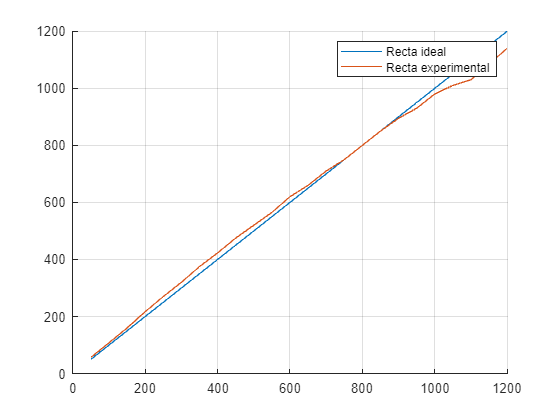

distancia_teorica=[50:50:1200];
distancia_medida = [57 108 160 217 270 320 375 423 475 520 565 620 660 710 750 800 850 895 930 980 1010 1030 1085 1140];
figure()
grid on
hold on
plot(distancia_teorica,distancia_teorica)
plot(distancia_teorica,distancia_medida)
legend("Recta ideal","Recta experimental")
hold off

Ahora, realizamos una regresión lineal para obtener la recta de ajuste de los datos experimentales.

pol = polyfit(distancia_teorica,distancia_medida,1)

pol =     0.9346   38.7862


Representamos la recta de ajuste con la ideal

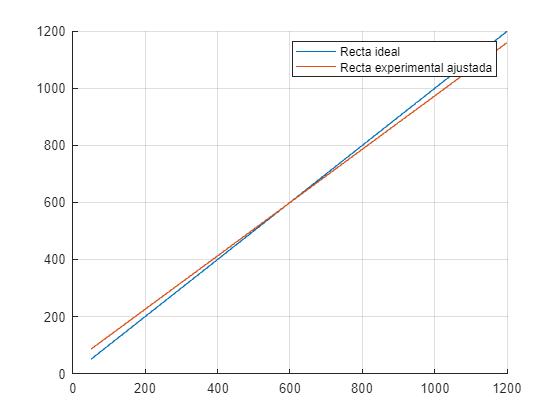

figure()
grid on
hold on
plot(distancia_teorica,distancia_teorica)
plot(distancia_teorica,polyval(pol,distancia_teorica))
legend("Recta ideal","Recta experimental ajustada")
hold off

Dado que las distancias que nos interesan que sean más precisas en cuanto a la medida del sensor son las más cercanas al robot, es decir, las distancias de menor valor, ajustaremos el offset y la ganancia de la recta de ajuste centrándola en el origen de las medida, es decir, en 5 cm.

Ajustamos el offset:

datos_ajustados = polyval(pol,distancia_teorica);

offset = datos_ajustados(1)-distancia_teorica(1);

for i = 1:1:24
    datos_ajustados(i) = datos_ajustados(i)-offset;
end

Comprobamos el ajuste centrado en el origen de las rectas:

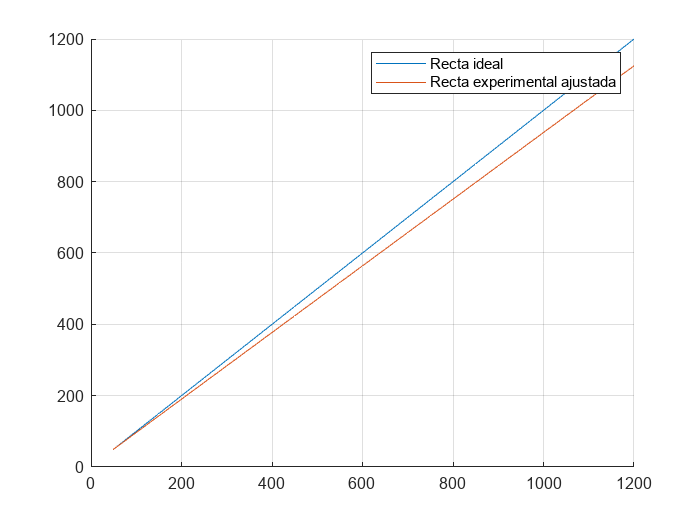

figure()
grid on
hold on
plot(distancia_teorica,distancia_teorica)
plot(distancia_teorica,datos_ajustados)
legend("Recta ideal","Recta experimental ajustada")
hold off

Ajustamos la ganancia

K = distancia_teorica(24)/datos_ajustados(24);
datos_ajustados = K.*datos_ajustados;

Comprobamos el ajuste de la ganancia

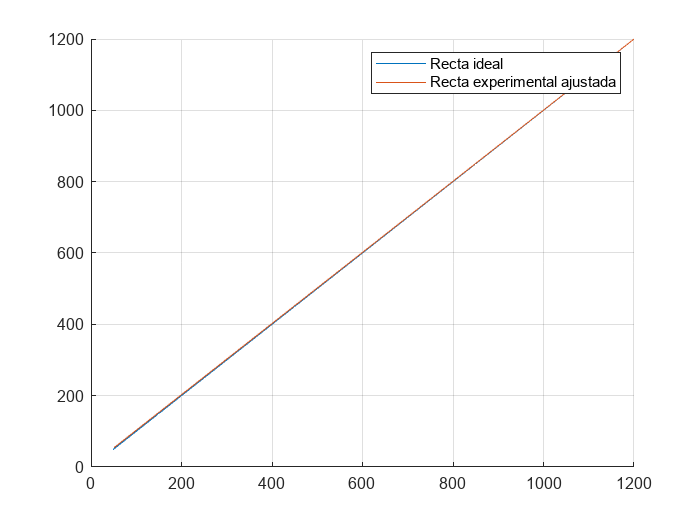

figure()
grid on
hold on
plot(distancia_teorica,distancia_teorica)
plot(distancia_teorica,datos_ajustados)
legend("Recta ideal","Recta experimental ajustada")
hold off

Representamos los datos experimentales ajustados en offset y ganancia

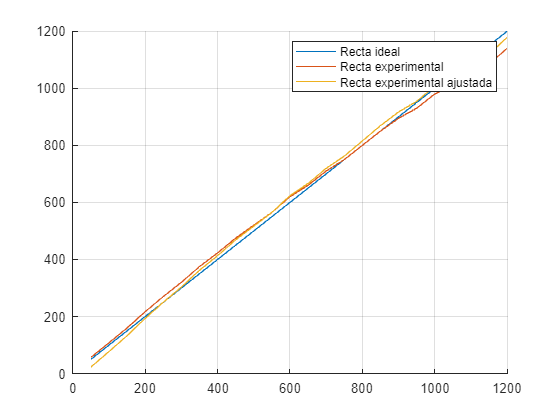

distancia_medida_ajustada = distancia_medida;

for i=1:1:24
    distancia_medida_ajustada(i)=(distancia_medida_ajustada(i)-offset)*K;
end


figure()
grid on
hold on
plot(distancia_teorica,distancia_teorica)
plot(distancia_teorica,distancia_medida)
plot(distancia_teorica,distancia_medida_ajustada)
legend("Recta ideal","Recta experimental","Recta experimental ajustada")
hold off

Comprobamos la disminución del error en el rango de medida del sensor al haber ajustado el offset y la ganancia del mismo.

error_inicial = 0;
error_ajustado = 0;

for i = 1:1:24
    error_inicial = error_inicial + (distancia_teorica(i)-distancia_medida(i))/(distancia_teorica(i)*24);
    error_ajustado = error_ajustado + (distancia_teorica(i)-distancia_medida_ajustada(i))/(distancia_teorica(i)*24);
end
 